TAsk 1:




%% EE252 Lab 06 - Task 1: Sunspot Data Import & Conversion
clc; clear; close all;

% 1. Specify filename
filename = 'SN_y_tot_V2.0.csv';

% 2. Configure import options for semicolon-delimited SILSO CSV
opts = detectImportOptions(filename, 'FileType', 'text');
opts.Delimiter = ';';
rawData = readmatrix(filename, opts);

% 3. Extract Year (Col 1) and Sunspot Number (Col 2)
allYears = floor(rawData(:, 1)); 
allSunspots = rawData(:, 2);

% 4. Filter strictly for years 1700 to 2025
validIdx = (allYears >= 1700) & (allYears <= 2025);
years = allYears(validIdx);
sunspots = allSunspots(validIdx);

% 5. Create structured table
sunspotTable = table(years, sunspots, 'VariableNames', {'Year', 'SunspotNumber'});

% 6. Save in .mat and .csv formats
save('sunspot_data.mat', 'sunspotTable', 'years', 'sunspots');
writetable(sunspotTable, 'sunspot_data.csv');

disp('Task 1 Complete: Saved sunspot_data.mat and sunspot_data.csv');

Task 1 Complete: Saved sunspot_data.mat and sunspot_data.csv


1. How did you find the data?

The sunspot dataset was obtained from SILSO ([https://www.sidc.be/SILSO/datafiles](https://www.sidc.be/SILSO/datafiles)), operated by the Royal Observatory of Belgium. SILSO serves as the primary global repository for historical solar activity records.

2. How was it downloaded?

The data was downloaded as a semicolon-separated text file (SN_y_tot_V2.0.csv) directly from the SILSO data portal archives ([https://www.sidc.be/SILSO/datafiles](https://www.sidc.be/SILSO/datafiles)). It contains total annual sunspot averages recorded continuously from 1700 to the present year.   

3. How did you convert the data to .mat and .csv format?

- **Importing:** Imported SN_y_tot_V2.0.csv into MATLAB using readmatrix with the delimiter option set to semicolon (;).   

- **Filtering:** Extracted Year (Column 1) and Sunspot Number (Column 2) and applied a logical index (allYears >= 1700) & (allYears <= 2025) to isolate the target date range.   

- **Table Creation & Export:** Formatted the two vectors into a structured MATLAB table with headers Year and SunspotNumber.   

- **Saving:** Exported the dataset using:

- save('sunspot_data.mat', 'sunspotTable', 'years', 'sunspots') to generate the binary .mat workspace file.   

- writetable(sunspotTable, 'sunspot_data.csv') to export the formatted CSV file.

Task 2:

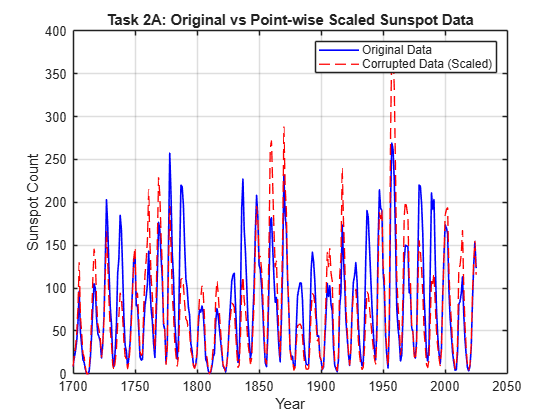

%% EE252 Lab 06 - Task 2: Data Corruption & Recovery Analysis (Corrected)
clc; clear; close all;

% Load cleaned dataset from Task 1
load('sunspot_data.mat'); 
N = length(sunspots);     


V = 1 + 0.5 * sin(2 * pi * (1:N)' / 50);

% Point-wise element-by-element multiplication
corrupted_vector = sunspots .* V;

% Plot Task 2A
figure('Name', 'Task 2A - Point-wise Scaling', 'Color', 'w');
plot(years, sunspots, 'b-', 'LineWidth', 1.2, 'DisplayName', 'Original Data');
hold on;
plot(years, corrupted_vector, 'r--', 'LineWidth', 1.0, 'DisplayName', 'Corrupted Data (Scaled)');
grid on; xlabel('Year'); ylabel('Sunspot Count');
title('Task 2A: Original vs Point-wise Scaled Sunspot Data');
legend('Location', 'northeast');



scale_factors = 1.5 + 0.2 * cos((1:N)');
M = diag(scale_factors);

% Corrupt data via matrix multiplication: Y = M * X
corrupted_matrix = M * sunspots;

% Recover original signal using matrix inverse: X = M^(-1) * Y
recovered_matrix = M \ corrupted_matrix;

% Plot Task 2B
figure('Name', 'Task 2B - Matrix Transformation Recovery', 'Color', 'w');
plot(years, sunspots, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Original Data');
hold on;
plot(years, recovered_matrix, 'go', 'MarkerSize', 3, 'DisplayName', 'Recovered Data (M^{-1} * Y)');
grid on; xlabel('Year'); ylabel('Sunspot Count');
title('Task 2B: Invertible Matrix Transformation & Exact Recovery');
legend('Location', 'northeast');



threshold = 79;

% Apply clipping limit (Saturation)
corrupted_clipped = sunspots;
clipped_mask = corrupted_clipped > threshold;
corrupted_clipped(clipped_mask) = threshold;

% Identify unclipped baseline points
unclipped_years = years(~clipped_mask);
unclipped_values = corrupted_clipped(~clipped_mask);

% Reconstruct peaks using 'pchip' interpolation (prevents boundary drops)
recovered_clipped = interp1(unclipped_years, unclipped_values, years, 'pchip', 'extrap');

% Ensure no negative sunspot values
recovered_clipped(recovered_clipped < 0) = 0;

% Plot Task 2C
figure('Name', 'Task 2C - Clipping & PCHIP Recovery', 'Color', 'w');
plot(years, sunspots, 'b-', 'LineWidth', 1.2, 'DisplayName', 'Original Data');
hold on;
plot(years, corrupted_clipped, 'r--', 'LineWidth', 1.2, 'DisplayName', sprintf('Clipped (Limit = %d)', threshold));
plot(years, recovered_clipped, 'm-.', 'LineWidth', 1.2, 'DisplayName', 'Approx. Recovery (PCHIP)');
grid on; xlabel('Year'); ylabel('Sunspot Count');
title(sprintf('Task 2C: Non-Invertible Clipping (Threshold = %d) & PCHIP Recovery', threshold));
legend('Location', 'northeast');
ylim([0, max(sunspots) + 30]);


rmse_matrix = sqrt(mean((sunspots - recovered_matrix).^2));
rmse_clipped = sqrt(mean((sunspots - recovered_clipped).^2));

fprintf('\n--- TASK 2 RECOVERY PERFORMANCE COMPARISON ---\n');


--- TASK 2 RECOVERY PERFORMANCE COMPARISON ---


fprintf('Matrix Recovery RMSE:  %.4e\n', rmse_matrix);

Matrix Recovery RMSE:  4.7482e-15


fprintf('Clipped Recovery RMSE: %.4f\n', rmse_clipped);

Clipped Recovery RMSE: 59.1016


2d:

Part B demonstrates exact signal recovery because the transformation matrix M is diagonal, linear and non-singular, so every output value corresponds to exactly one original data point. Applying the matrix inverse M^(-1) completely reverses the scaling without any loss of data. The resulting Root Mean Square Error (RMSE) is approximately 4.75 × 10^(-15), which is only floating-point round-off and means the reconstruction is exact.

In contrast, Part C applies a hard clipping threshold of 79. This is a non-linear, many-to-one mapping: every value above 79 is flattened to the same number, so the true peak information is permanently lost and exact inversion is impossible. PCHIP interpolation using the unclipped points only bridges the clipped regions. Because it is shape-preserving, it cannot rise above the surrounding data, so the peak amplitudes are not recovered. Near the end of the record, where the last points are clipped, the extrapolation also drops toward zero. The result is a much higher error (RMSE = 59.10) that quantifies the unavoidable information loss caused by clipping.

Task 3:



% 1. Load cleaned dataset from Task 1
load('sunspot_data.mat');

% 2. Extract Solar Cycle 22 (1985 to 1996)
cycle_idx = (years >= 1985) & (years <= 1996);
t_cycle = years(cycle_idx);
y_cycle = sunspots(cycle_idx);

% 3. Model Parameters Initial Guess: y(t) = a - b * cos(c * (t - d))
a0 = mean(y_cycle);                     % Average level
b0 = (max(y_cycle) - min(y_cycle)) / 2;  % Peak height
c0 = 2 * pi / 11;                        % ~11-year period frequency
d0 = 1985;                               % Phase start year

initial_params = [a0, b0, c0, d0];

% Define cosine model and error function
model_func = @(p, t) p(1) - p(2) * cos(p(3) * (t - p(4)));
cost_func = @(p) sum((y_cycle - model_func(p, t_cycle)).^2);

% Run optimization to find best fitting parameters
fitted_params = fminsearch(cost_func, initial_params);

a_fit = fitted_params(1);
b_fit = fitted_params(2);
c_fit = fitted_params(3);
d_fit = fitted_params(4);

% Generate model output
y_model = model_func(fitted_params, t_cycle);

% 4. Compute Residual Error and Power Metrics
residuals = y_cycle - y_model;

P_signal = mean(y_cycle.^2);
P_residual = mean(residuals.^2);
P_residual_dB = 10 * log10(P_residual / P_signal);

% 5. Display Results
fprintf('\n--- TASK 3 MODEL FITTING RESULTS (1985-1996) ---\n');


--- TASK 3 MODEL FITTING RESULTS (1985-1996) ---


fprintf('DC Offset (a):        %.2f\n', a_fit);

DC Offset (a):        108.71


fprintf('Amplitude (b):        %.2f\n', b_fit);

Amplitude (b):        100.08


fprintf('Angular Freq (c):     %.4f rad/year (Period ~ %.2f years)\n', c_fit, 2*pi/c_fit);

Angular Freq (c):     0.6533 rad/year (Period ~ 9.62 years)


fprintf('Phase Offset (d):     %.2f years\n', d_fit);

Phase Offset (d):     1985.41 years


fprintf('Fitted Equation:      y(t) = %.2f - %.2f * cos(%.4f * (t - %.2f))\n', a_fit, b_fit, c_fit, d_fit);

Fitted Equation:      y(t) = 108.71 - 100.08 * cos(0.6533 * (t - 1985.41))


fprintf('Signal Power:         %.2f\n', P_signal);

Signal Power:         13821.98


fprintf('Residual Power:       %.2f\n', P_residual);

Residual Power:       255.92


fprintf('Residual Power (dB):  %.2f dB\n', P_residual_dB);

Residual Power (dB):  -17.32 dB


10*log10(P_residual / var(y_cycle,1))

ans = -13.3879


% 6. Plot Task 3 Deliverable
figure('Name', 'Task 3 - Cosine Model Fit', 'Color', 'w');
plot(t_cycle, y_cycle, 'b-o', 'LineWidth', 1.5, 'MarkerFaceColor', 'b', 'DisplayName', 'Measured Sunspots');
hold on;
plot(t_cycle, y_model, 'r--', 'LineWidth', 2.0, 'DisplayName', 'Cosine Model Fit');
stem(t_cycle, residuals, 'k:', 'LineWidth', 1.0, 'DisplayName', 'Residual Error');
grid on; xlabel('Year'); ylabel('Sunspot Count');
title('Task 3: Cosine Model Fitting (1985–1996 Solar Cycle)');
legend('Location', 'northeast');

c) Comment on Goodness of Fit

**Overall fit quality:** The residual power ratio is -17.32 dB, so the residual power (255.92) is about 54 times smaller than the signal power (13821.98), or about 1.9% of it. The fitted model is y(t) = 108.71 - 100.08 cos(0.6533 (t - 1985.41)), which follows the rise and fall of the cycle well. Note that the signal power includes the DC level (the mean is about 91), so this ratio looks better than a variance-based one, which is -13.4 dB. The fit is good, but it uses four parameters on only 12 data points.

**Limitations/discrepancies:** The fitted period is about 9.62 years, shorter than the nominal 11-year solar cycle. This is likely because only one 12-point cycle was fitted and the cycle is not a perfect cosine.

a. **Asymmetry:** Real solar cycles rise faster toward the peak than they decay, whereas a cosine is strictly symmetric. This causes the largest residuals on the rising side (1987 and 1989).

b. **Cycle-to-cycle variability:** The annual averages contain irregular variations, such as the double peak around 1989 to 1991, that a single smooth cosine cannot reproduce.